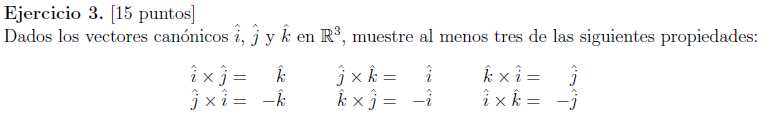

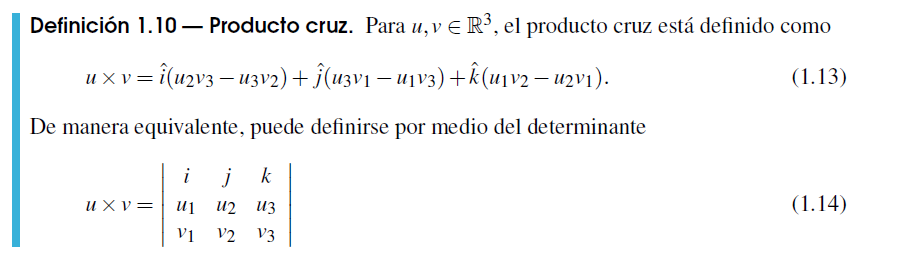

**Definicion de un vector canónico:**

Aquel donde todas sus componentes son 0 exceptuando 1. De tal modo que para $\Re^3$

$i=\left\lbrack \begin{array}{c}
1i\\
0j\\
0k
\end{array}\right\rbrack$,$j=\left\lbrack \begin{array}{c}
0i\\
1j\\
0k
\end{array}\right\rbrack$,$k=\left\lbrack \begin{array}{c}
0i\\
0j\\
1k
\end{array}\right\rbrack$,

i = [1 0 0];
j = [0 1 0];
k = [0 0 1];

Utilizando la definición 1.10 del producto cruz para mostrar la siguiente propiedad  :


$$\left.i\times j=\left(0*0\right)-\left(0*0\right)\right)i+\left(\left(0*1\right)-\left(1*0\right)\right)j+\left(\left(1*1\right)-\left(0*0\right)\right)\;k$$



$$i\times j=\left(0\right)i+\left(0\right)j+\left(1\right)\;k$$



$$i\times j=\;\left\lbrack \begin{array}{c}
0i\\
0j\\
1k
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
k
\end{array}\right\rbrack$$


Utilizando la definición 1.10 del producto cruz para mostrar la siguiente propiedad  :


$$\left.j\times i=\left(1*0\right)-\left(0*0\right)\right)i+\left(\left(0*1\right)-\left(0*0\right)\right)j+\left(\left(0*0\right)-\left(1*1\right)\right)\;k$$



$$j\times i=\left(0\right)i+\left(0\right)j-\left(1\right)\;k$$



$$j\times i=\;\left\lbrack \begin{array}{c}
0i\\
0j\\
-1k
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
-k
\end{array}\right\rbrack$$


Utilizando la definición 1.10 del producto cruz para mostrar la siguiente propiedad :


$$\left.j\times \;k=\left(1*1\right)-\left(0*0\right)\right)i+\left(\left(0*0\right)-\left(0*1\right)\right)j+\left(\left(0*0\right)-\left(1*0\right)\right)\;k$$



$$j\times k=\left(1\right)i+\left(0\right)j+\left(0\right)\;k$$



$$j\times i=\;\left\lbrack \begin{array}{c}
1i\\
0j\\
0k
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
i\\
0\\
0
\end{array}\right\rbrack$$


% cross(i,j)
% cross(j,i)
% cross(j,k)
% cross(k,j)
% cross(k,i)
% cross(i,k)

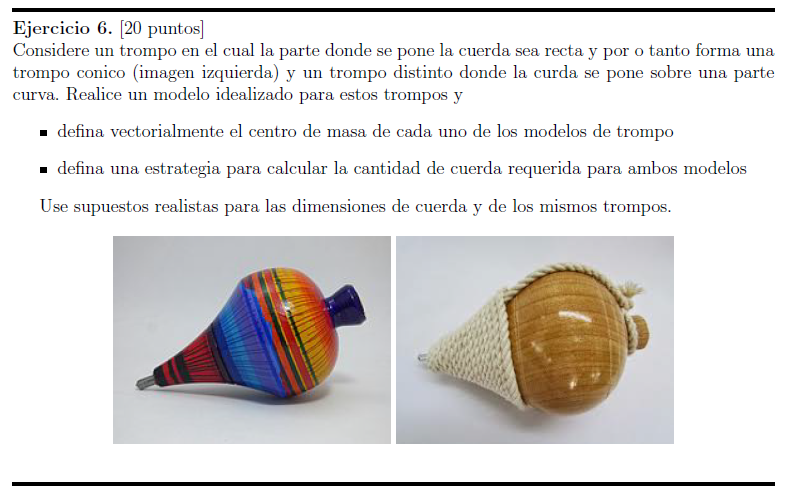

t = linspace(0,36*pi,10000);
a = 1.05;

 

z = (1/36)*t/pi;
x = (.2+(a*t/36/pi)).*sin(t);
y = (.2+(a*t/36/pi)).*cos(t);

 

figure
plot3(x,y,z);
xlabel ('x-axis')
ylabel ('y-axis')
zlabel ('z-axis')
axis equal
grid on
hold on



Parael centro de masa:


$${\mathrm{COM}}_x =\frac{m_1 x_1 +m_2 x_2 +\cdots m_n x_n }{m_1 +m_2 +\cdots +m_n }$$



$${\mathrm{COM}}_y =\frac{m_1 y_1 +m_2 y_2 +\cdots m_n y_n }{m_1 +m_2 +\cdots +m_n }$$



$${\mathrm{COM}}_z =\frac{m_1 z+m_2 z_2 +\cdots m_n z_n }{m_1 +m_2 +\cdots +m_n }$$


Utilizando el vectorde velocidad. En este caso la aceleracion

syms t;
z = (1/36)*t/pi;
x = (.2+(a*t/36/pi)).*sin(t);
y = (.2+(a*t/36/pi)).*cos(t);

% Segunda Derivada wrt t
xdiff2 = diff(x,t,2)

$$xdiff2 = \frac{7\,\cos\left(t\right)}{120\,\pi }-\sin\left(t\right)\,\left(\frac{7\,t}{240\,\pi }+\frac{1}{5}\right)$$

ydiff2 = diff(y,t,2)

$$ydiff2 = -\cos\left(t\right)\,\left(\frac{7\,t}{240\,\pi }+\frac{1}{5}\right)-\frac{7\,\sin\left(t\right)}{120\,\pi }$$

zdiff2 = diff(z,t,2)

$$zdiff2 = 0$$

assume(t,'clear');
t = linspace(0,36*pi,100);
z = (1/36)*t/pi;
x = (.2+(a*t/36/pi)).*sin(t);
y = (.2+(a*t/36/pi)).*cos(t);


xDev = ((7.*cos(t))/(120.*pi)) - (sin(t).*(((7.*t)/(240.*pi))+(1/5)))

xDev =     0.0186   -0.1839   -0.1793    0.0475    0.2373    0.1524   -0.1269   -0.2741   -0.0981    0.2111    0.2861    0.0186   -0.2900   -0.2675    0.0804    0.3528    0.2155   -0.1900   -0.3896   -0.1309    0.2993    0.3922    0.0186   -0.3961   -0.3557    0.1132    0.4683    0.2786   -0.2531   -0.5051   -0.1638    0.3875    0.4984    0.0186   -0.5022   -0.4439    0.1461    0.5838    0.3416   -0.3161   -0.6205   -0.1967    0.4756    0.6045    0.0186   -0.6084   -0.5320    0.1790    0.6992    0.4047


yDev = -cos(t).*((((7.*t)/(240.*pi))+(1/5))) - ((7.*sin(t))/120.*pi)

yDev =    -0.2000   -0.2542    0.0064    0.2741    0.2159   -0.1138   -0.3209   -0.1424    0.2217    0.3320    0.0396   -0.3167   -0.3027    0.0828    0.3860    0.2325   -0.2119   -0.4190   -0.1258    0.3336    0.4084   -0.0089   -0.4333   -0.3511    0.1592    0.4979    0.2491   -0.3101   -0.5172   -0.1092    0.4456    0.4848   -0.0574   -0.5500   -0.3996    0.2356    0.6099    0.2657   -0.4082   -0.6153   -0.0926    0.5575    0.5612   -0.1058   -0.6667   -0.4480    0.3120    0.7218    0.2823   -0.5064


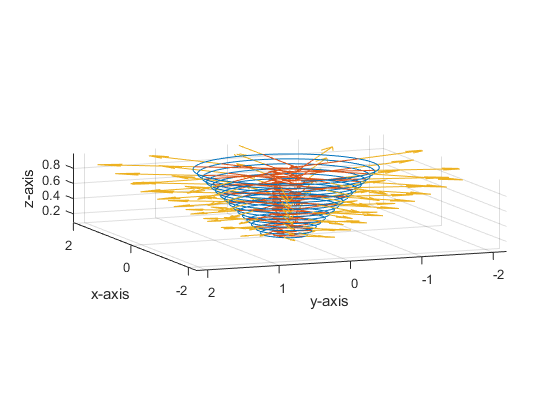

zDev = zeros(size(t));

quiver3(x, y, z, xDev, yDev, zDev, 0)
hold on 
quiver3(x, y, z, -xDev, -yDev, -zDev, 0)